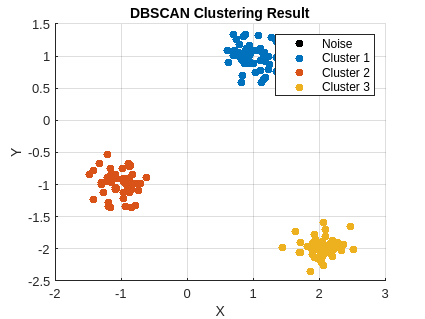

% Generate a simple dataset
rng(1); % For reproducibility
data1 = [randn(50,2)*0.2 + ones(50,2); % Cluster 1
         randn(50,2)*0.2 - ones(50,2); % Cluster 2
         randn(50,2)*0.2 + [2 -2]];    % Cluster 3
     
% DBSCAN parameters
eps = 0.7;
MinPts = 4;

% Run DBSCAN algorithm
clusters = DBSCAN(data1, eps, MinPts);

% Plot the results
figure;
hold on;
colors = lines(max(clusters)+1); % Choose colors for clusters
for i = 0:max(clusters)
    if i == 0
        scatter(data1(clusters==i,1), data1(clusters==i,2), 36, 'k', 'filled'); % Noise points
    else
        scatter(data1(clusters==i,1), data1(clusters==i,2), 36, colors(i,:), 'filled'); % Cluster points
    end
end
title('DBSCAN Clustering Result');
xlabel('X');
ylabel('Y');
legend('Noise', 'Cluster 1', 'Cluster 2', 'Cluster 3');
grid on;
hold off;